# Test Script for the powerFromResistivity Function

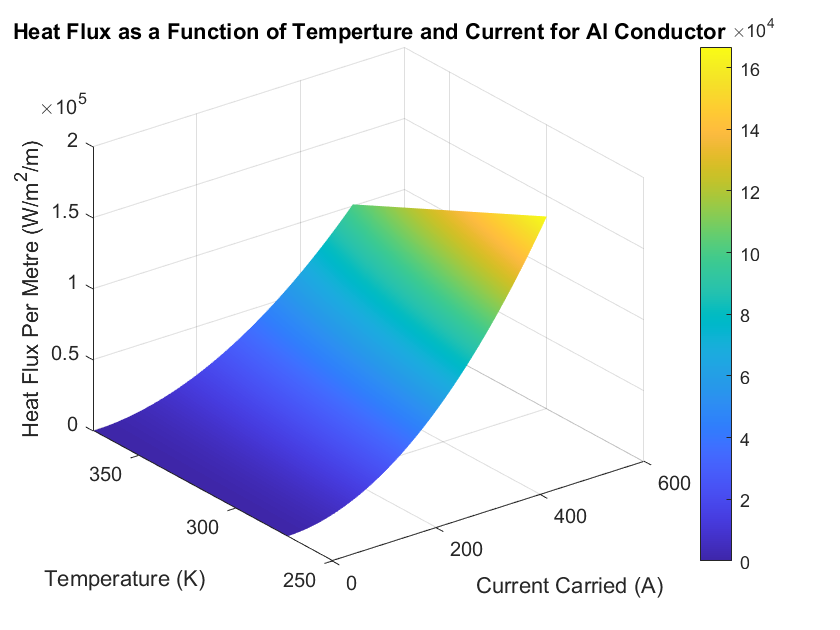

clearvars

% Cable parameters
iToTest = 0:10:500; % Amps
cableState.I = iToTest(1);
cableState.Area = 300 / 1e6; % 300mm^2 in m^2;

state.u = (0:1:100) + 273.3;
q = zeros(size(state.u, 2), size(iToTest, 2));

for i = 1:1:size(iToTest, 2)
    cableState.I = iToTest(i);
    q(:, i) = powerFromResistivity([], state, cableState);
end

% plot(state.u, q)
surf(iToTest, state.u, q, ...
    'LineStyle', 'none', ...
    'FaceColor', "interp")
xlabel('Current Carried (A)')
ylabel('Temperature (K)')
zlabel('Heat Flux Per Metre (W/m^2/m)')
title('Heat Flux as a Function of Temperture and Current for Al Conductor')
colorbar

Copyright © 2020 The MathWorks, Inc.